# Airline Round Trip Payload-Fuel Optimizer

#### َ**Alireza Ghaderi **

#### **p30planets@gmail.com**

#### **Ghaderi@alumsharif.org**

#### [**https://www.linkedin.com/in/alireza787b/**](https://www.linkedin.com/in/alireza787b/)

- **Remember to first run Fuel Estimator in order to create fullData.mat.**

- **If you want to create your own Regression model, change it from svm4Full.mat to your own file.**

- **If you want to use Auto Flight info mode, you need run Fuel Estimator with your own Data filled with flight time, block time , etc**

## Initilization 

clear
clc
close
format longG;
global trainedModel param1;
load ../Fuel_Estimator/svm4Full.mat ;

load ../fullData;

## **  Input Data**

### **Route Data**


param1.apt1 = "TBZ";
param1.apt2 = "IST";
auto = true;
param1.distance = getDistance(param1.apt1,param1.apt2);
param1.fieldElev1 = getElev(param1.apt1);
param1.fieldElev2 = getElev(param1.apt2);
if auto
idx =  (data.Origin == param1.apt1 & data.Destination == param1.apt2) ;
    dataCut = data(idx,:);
param1.FlightTime1 = mean(dataCut.FlightTime);
param1.BlockTime1 = mean(dataCut.BlockTime);
clear dataCut;
idx =  (data.Origin == param1.apt2 & data.Destination == param1.apt1) ;
    dataCut = data(idx,:);
param1.FlightTime2 = mean(dataCut.FlightTime);
param1.BlockTime2 = mean(dataCut.BlockTime);
end

### Flight Operation Data


param1.averagePaxWeightKG = 100;
if ~auto
param1.FlightTime1 = 0 ;
param1.BlockTime1 = 0 ;
param1.FlightTime2 = 0 ;
param1.BlockTime2 = 0;
param1.fieldElev1 = 0 ;
param1.fieldElev2 = 0 ;
param1.distance = 0 ;
end
param1.offBlock1 = "2022-08-17 10:00" ;
param1.offBlock2 = "2022-08-17 12:00" ;
param1.ticketPrice1 = 5000 ;
param1.ticketPrice2 = 2000;
param1.cargoPrice1 = 0;
param1.cargoPrice2 = 0;
param1.fuelPrice1 = 1;
param1.fuelPrice2 = 99999;
param1.fixedCostsPerLeg = 0;
param1.cargoCost1 = 100;
param1.cargoCost2 = 100;
param1.costsPerPax1 = 0;
param1.costsPerPax2 = 0;
param1.costsPerHour1 = 0;
param1.costsPerHour2 = 0;
param1.MTOW1 = 70000;
param1.MTOW2 = 72000;
param1.fuelTresh = 3000;
param1.MLW1 = 63000;
param1.MLW2 = 63000;
param1.maxFuelTankKg = 20000;
param1.maxZeroFuelWeight = 55300;
param1.emptyWeight = 39000;
param1.maxPax  =160;
param1.maxCargo = 0;

zeroFuelWeight = param1.maxZeroFuelWeight;
maxFuelTankKg = param1.maxFuelTankKg;



## Solver Initilization and Definition

num = 6;
xs(1,:) = [15000 0 10000 10000 0 0];
numOfStarts = 10;
for i=2:numOfStarts
xs(i,:) = [ randi([param1.fuelTresh param1.maxFuelTankKg]) ...
    randi([0 param1.maxFuelTankKg - param1.fuelTresh ]) ...
    randi([0 param1.maxPax*param1.averagePaxWeightKG]) ... 
    randi([0 param1.maxPax*param1.averagePaxWeightKG]) ...
    0 ...
    0 ];
end
n0 = 500;
%stpoints = RandomStartPointSet('NumStartPoints',40);
output = zeros(numOfStarts,7);
constraintTresh = 1;

**Optimization Task**

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


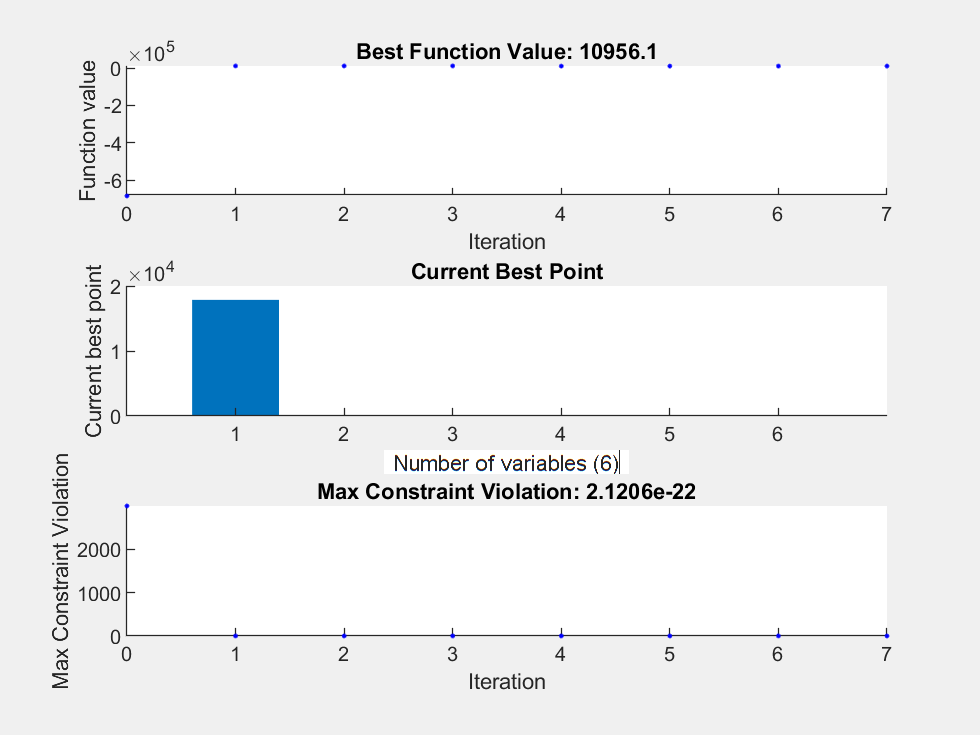

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


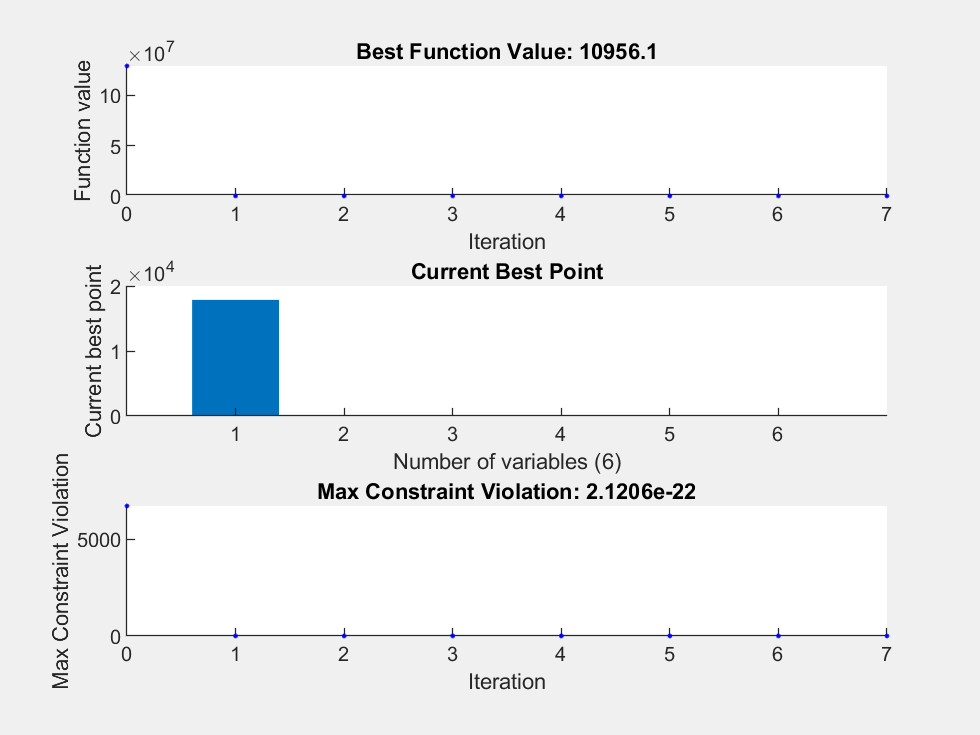

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


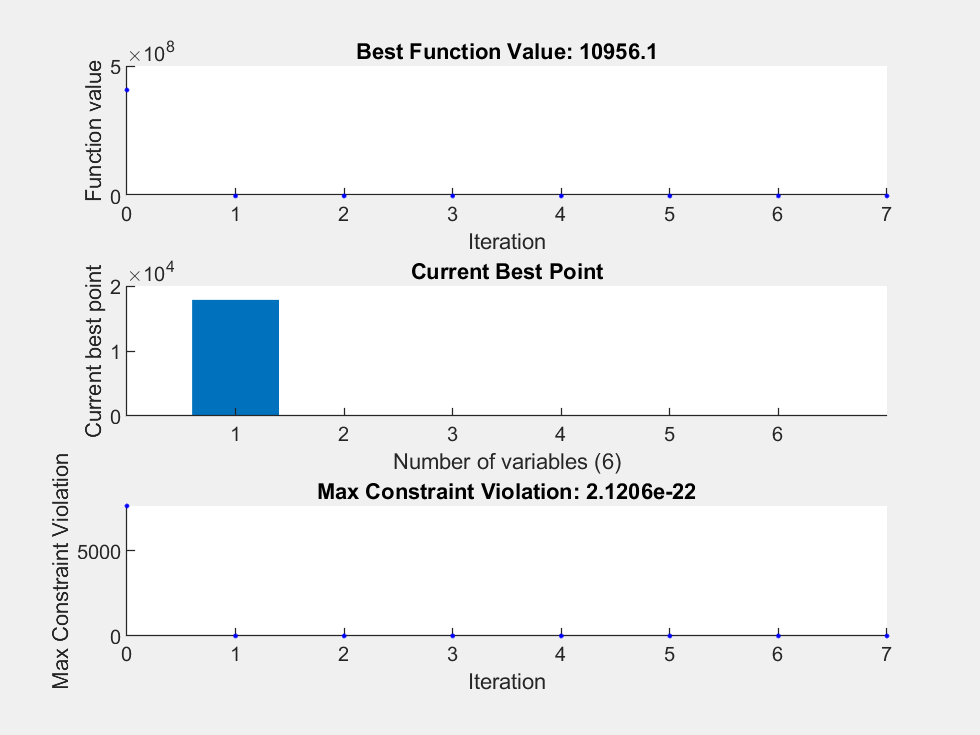

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


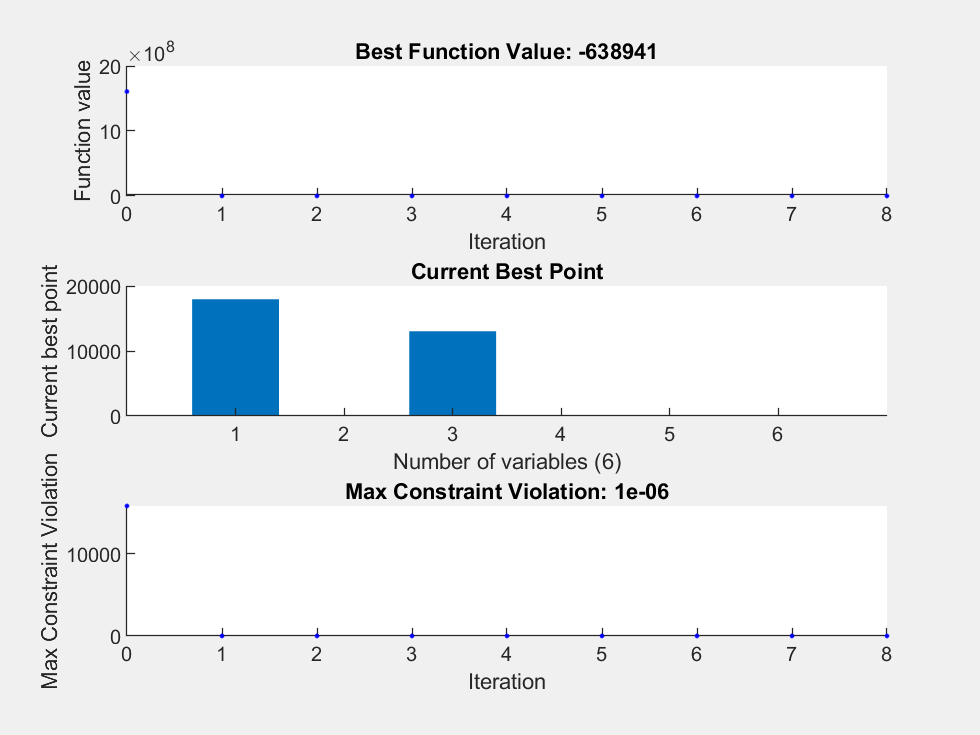

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


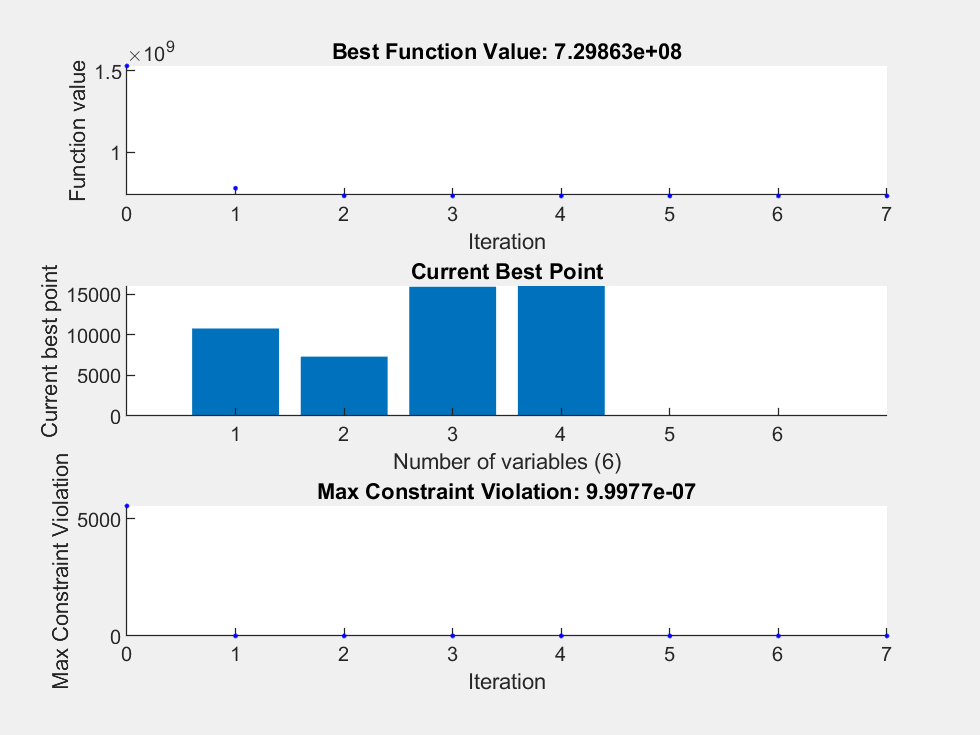

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


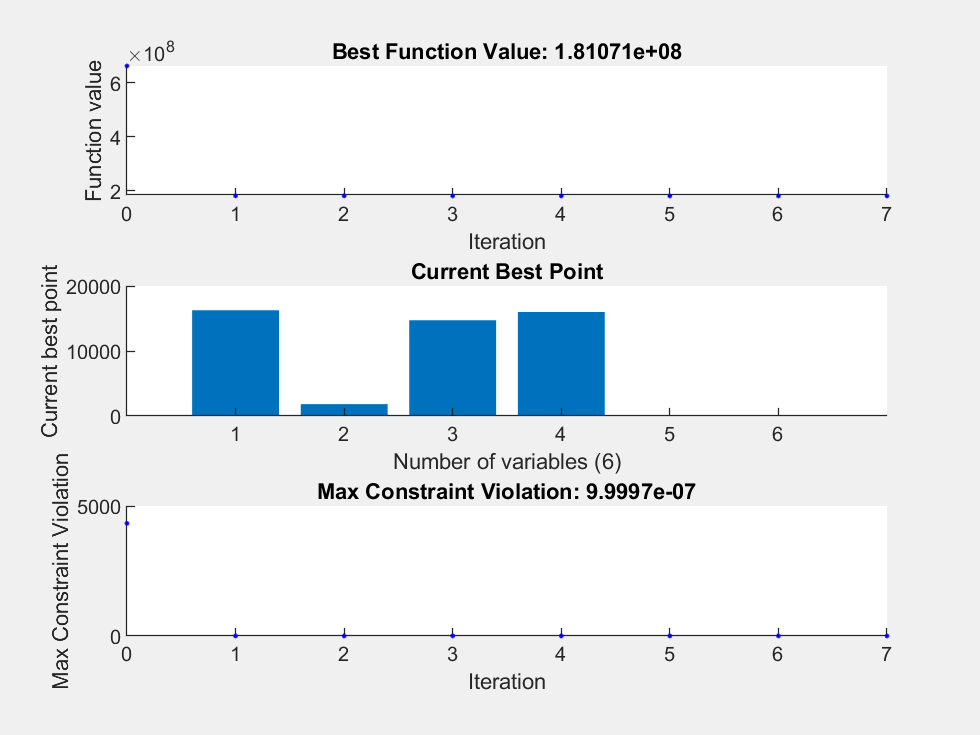

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


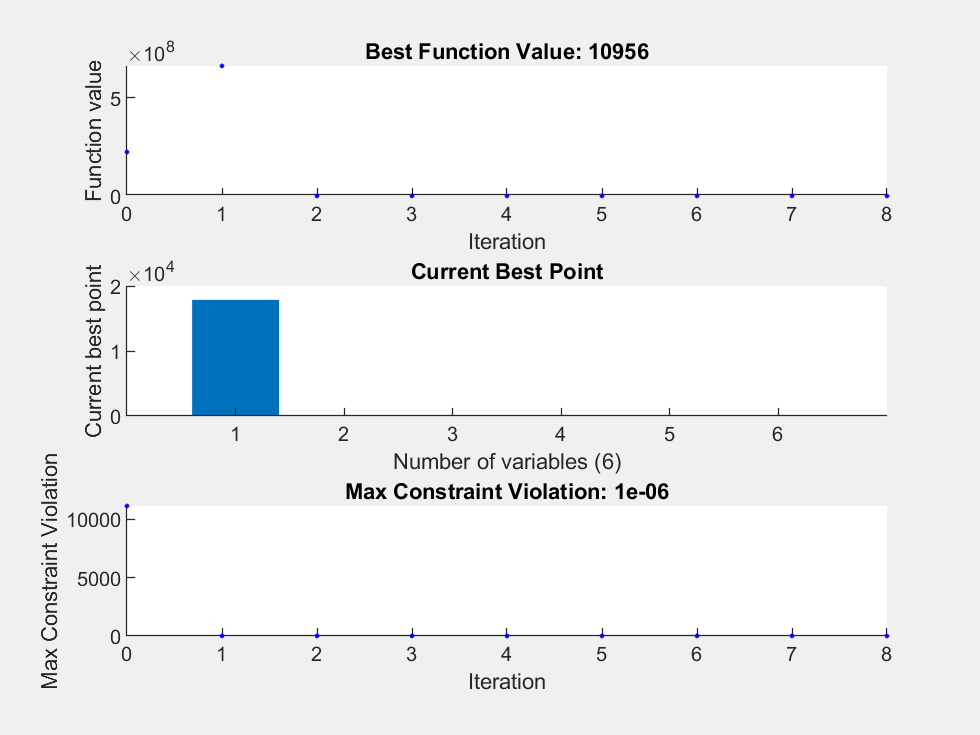

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


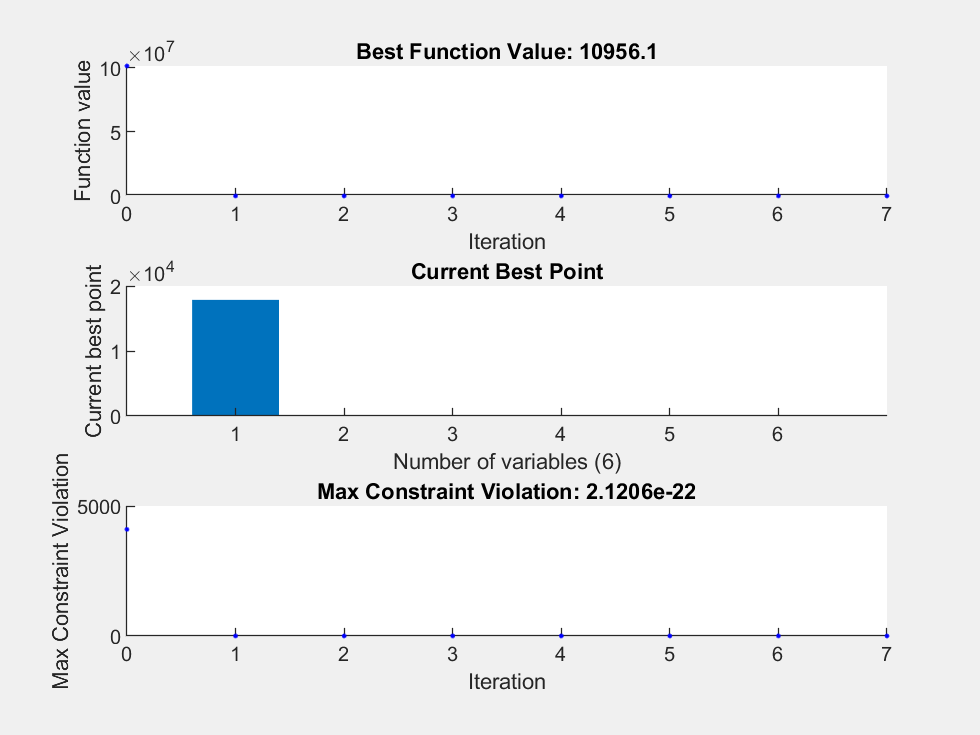

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


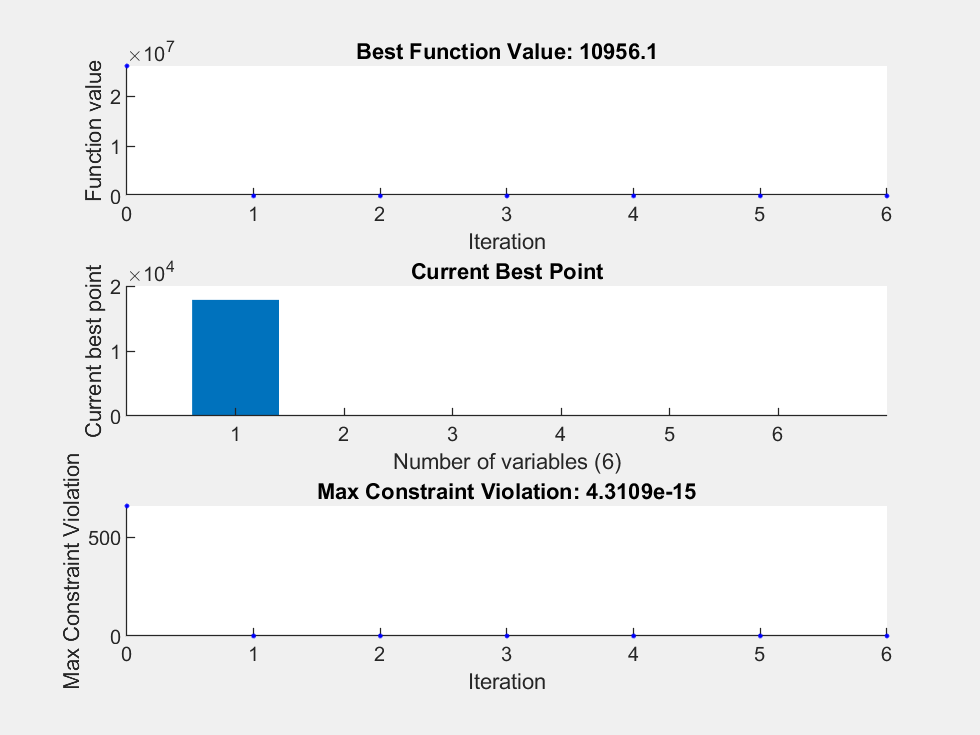

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


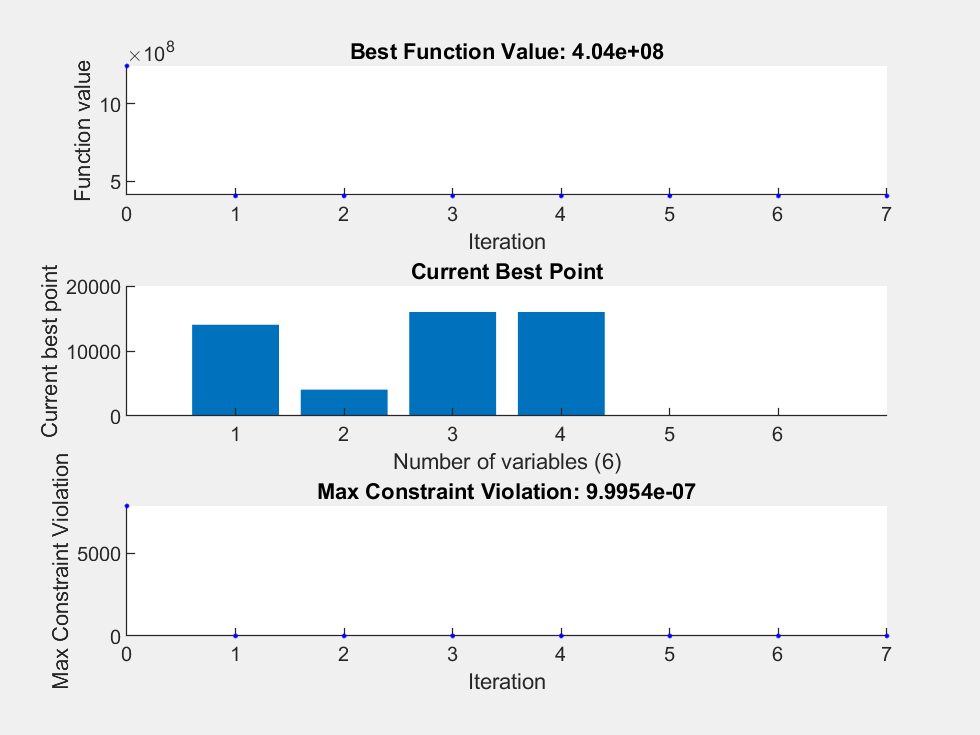

for idx=1:numOfStarts
x0 = xs(idx,:);


% Set nondefault solver options
options = optimoptions("patternsearch","UseCompleteSearch",true,"PlotFcn",...
    ["psplotbestf","psplotbestx","psplotmaxconstr"]);

% Solve
[solution,objectiveValue] = patternsearch(@costFunctionSolver,x0,[],[],[],[],...
    [],[],@constraintFcnSolver,options);

% Clear variables
clearvars options

temp = zeros(1,7);
temp(1,1:6) = solution;
temp(1,7) = -objectiveValue;
    if ~isempty(find(constraintFcnSolver(solution) >constraintTresh, 1))
    temp(1,7) = 0;
    end
output(idx,:) = temp;

uplift1 =        17958


uplift2 =     -1


end

pax1 =    131


pax2 =      1


bestIdx = find( output(:,7) == max(output(:,7)) );

cargo1 =     -1


output(:,3) = ceil(output(:,3)/param1.averagePaxWeightKG);

cargo2 =      0


output(:,4) = ceil(output(:,4)/param1.averagePaxWeightKG);

revenue = int32
   638941


## **Final Output**


uplift1 = floor(output(bestIdx,1))
uplift2 = floor(output(bestIdx,2))
pax1 = floor(output(bestIdx,3))
pax2 = floor(output(bestIdx,4))
cargo1 = floor(output(bestIdx,5))

FinalOutput = 10×7 table
    UpFuel1    UpFuel2    Pax1    Pax2    Cargo1    Cargo2     Revenue  
    _______    _______    ____    ____    ______    ______    __________

     17959         0      131       1       0         0           638941
     17856         0        1       1       0         0           -10956
     17856         0        1       1       0         0           -10956
     17856         0        1       1       0         0           -10956
     17856         0        1       1       0         0           -10956
     17856         0        1       1       0         0           -10956
     17856         0        1       1       0         0           -10956
     16265      1821      148     160       0         0       -181071475
     1

cargo2 = floor(output(bestIdx,6))
revenue = int32(output(bestIdx,7))



%output = sort(output,1,"descend");
cleanOutput = int32(output);
varNames = ["UpFuel1","UpFuel2","Pax1","Pax2","Cargo1","Cargo2","Revenue"];
varTypes = ["int32","int32","int32","int32","int32","int32","int64"];
FinalOutput = array2table(cleanOutput,"VariableNames",varNames);
FinalOutput = sortrows(FinalOutput,'Revenue','descend')